# Finding a 2D SSM for a FE model of a von Kármán beam 

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of a scalar quantity. In this example, we measure the midpoint displacement of a clamped-clamped von Kármán beam. [1]

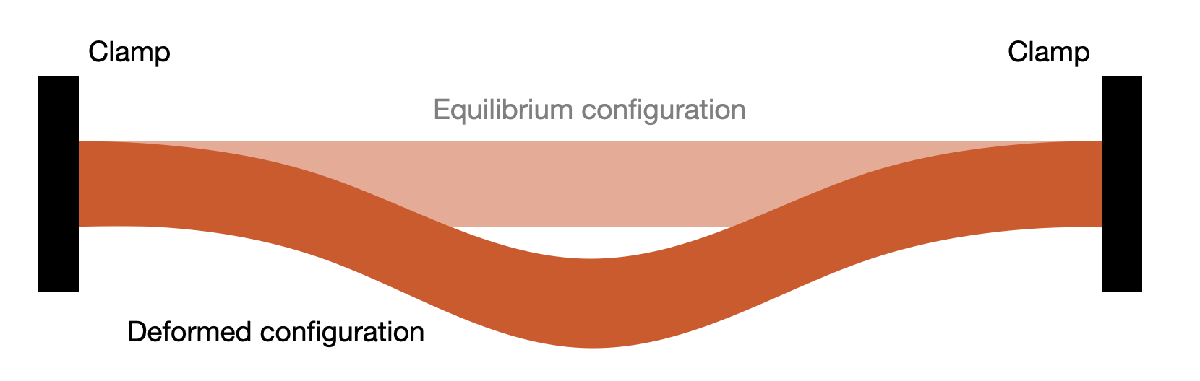

See [1] for the details of this model, and [2] the description of this example.

[1] S. Jain, P. Tiso, and G. Haller, Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds, *Journal of Sound and Vibration* 423 (2018) 195-211. [https://doi.org/10.1016/j.jsv.2018.01.049](https://doi.org/10.1016/j.jsv.2018.01.049) 

[2] Cenedese, M., Marconi, J., Haller, G., & Jain, S. (2023). Data-assisted non-intrusive model reduction for forced nonlinear finite elements models. Preprint: [arXiv: 2311.17865](https://arxiv.org/abs/2311.17865) 

The finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}   & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}   \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clearvars 
close all
clc

% Setup colors
colors = colororder; colSSMT = 5; colSSML = 7; colFOM = 1;

## Generate model

Building FE model


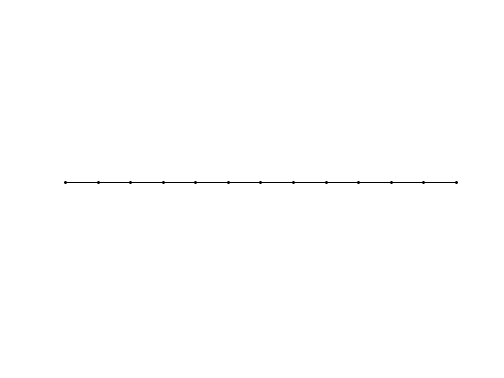

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


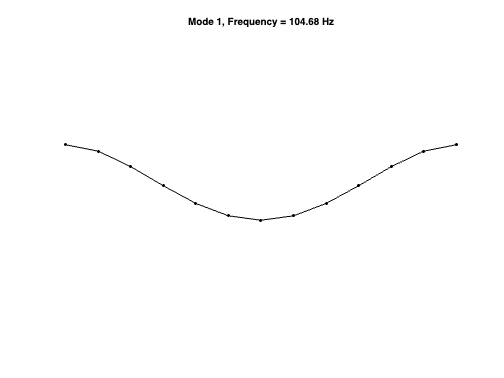

Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


nElements = 12;
[M, C, K, fnl, fExt, outdof, PlotFieldonDefMesh] = buildModel(nElements);

n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);
% Conservative mode shapes
[W,A,V] = linearpart(M,C,K,n);

   1.0e+10 *

    0.0000
    0.0003
    0.0013
    0.0035
    0.0077
    0.0152
    0.0257
    0.0271
    0.0452
    0.0715
    0.1047
    0.1081
    0.1535
    0.2424
    0.2538
    0.3490
    0.4480
    0.4848
    0.6698
    0.7350
    0.9193
    1.1200
    1.2534
    1.6194
    1.6948
    2.2400
    2.2616
    2.9463
    2.9576
    3.6764
    3.6861
    4.2586
    4.2769



## Define master modes and linear part of the dynamics

We initialize the base properties of the SSM, i.e., its linear part, which we know from the linear dynamics of the model. In this case, we target the slow two-dimensional SSM of the system. 

masterModes = [1 2]; % Modal displacements and modal velocities
Ve = V(:,masterModes); % Mode shape
We = W(masterModes,:); % Projection to mode shape
Ae = full(We*A*Ve) % Reduced, linearized dynamics

Ae = 1.0e+05 *

         0    0.0000
   -4.3260   -0.0001


SSMDim = length(masterModes);

% Load and displacement vector: midpoint displacement
displacementVector = zeros(1,n); displacementVector(outdof) = 1;
loadVector = zeros(n,1); loadVector(outdof) = 1; %  could also be set as modal ones

## Load static analysis and plot

We characterize the linear and nonlinear regimes via a static analysis, which serves to pick appropriate initial conditions for the trajectories we need to learn the SSM from data.

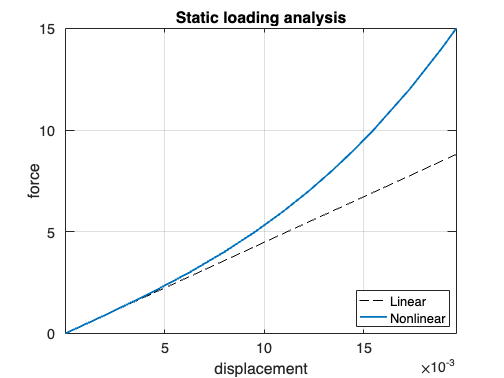

% Define some loading coefficients
loadCoefficients = [0.01:0.01:0.09 0.1:0.1:0.9 1:1:10 12 14 15]*1e3;
nLoads = length(loadCoefficients);
wlin = (K\loadVector);
w0 = loadCoefficients(1)*wlin; % linear initial guess
displacementLinear = loadCoefficients*(displacementVector*wlin);

% Solve nonlinear static analysis
IC = zeros(2*n,nLoads); displacementNonlinear = zeros(1,nLoads);
options = optimoptions('fsolve', 'MaxFunctionEvaluations', 200*n, 'Display', 'off');
for iLoad = 1:nLoads
    f_eq = @(w)([zeros(n) M]*F(0,[w; zeros(n,1)]) + loadVector*loadCoefficients(iLoad));
    [w0, ~, exitflag, output] = fsolve(f_eq, w0, options);
    if exitflag <= 0
        error('Warning: No solution found for loading configuration')
    end
    IC(:,iLoad) = [w0; zeros(n,1)]; displacementNonlinear(iLoad) = displacementVector*w0;
end

% Plot results
fig = customFigure(); classicColors = colororder;
plot(displacementLinear,loadCoefficients/1e3,'k--','Linewidth',1,'DisplayName','Linear')
plot(displacementNonlinear,loadCoefficients/1e3,'Color',classicColors(1,:),'Linewidth',2,'DisplayName','Nonlinear')
legend('location','SE')
xlim(abs([displacementNonlinear([1 end])]))
xlabel('displacement'); 
ylabel('force'); 
title('Static loading analysis');

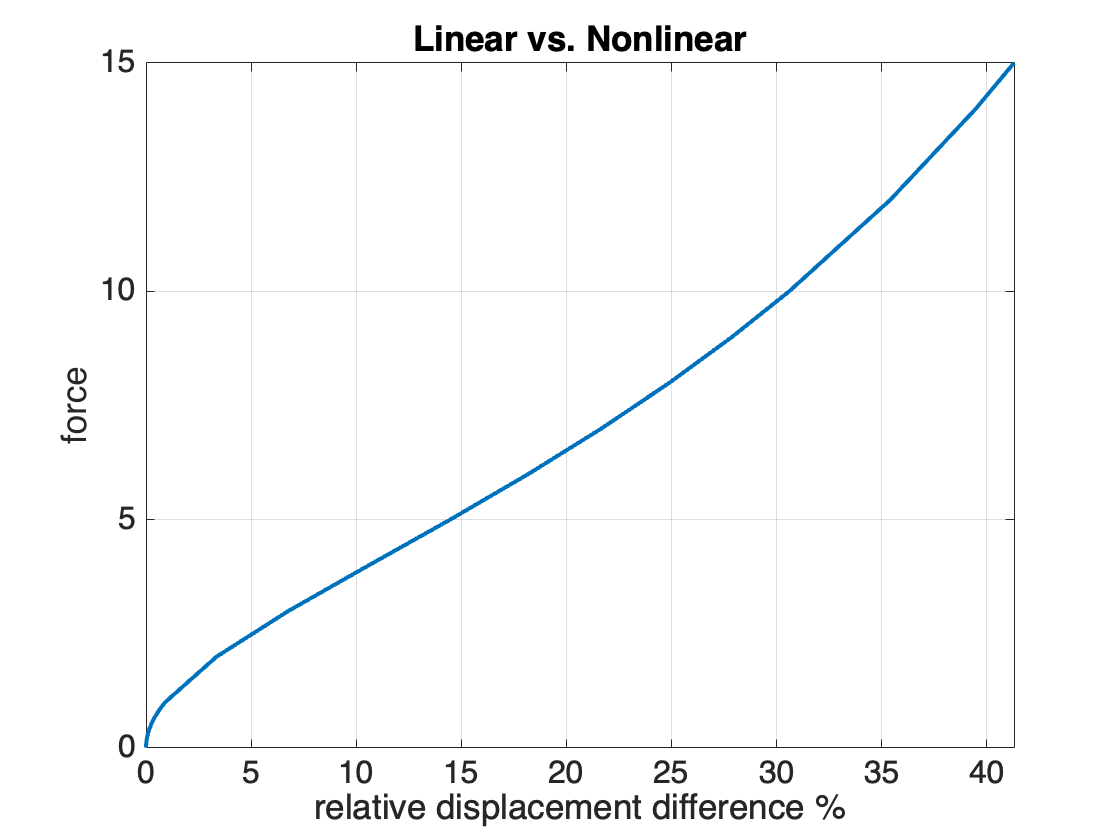


fig = customFigure(); classicColors = colororder;
displacementDifference = abs((displacementNonlinear-displacementLinear))./abs(displacementLinear);
plot(displacementDifference*100,loadCoefficients/1e3,'Color',classicColors(1,:),'Linewidth',2)
xlim([0 max(displacementDifference)]*100)
xlabel('relative displacement difference %'); 
ylabel('force'); 
title('Linear vs. Nonlinear')

Pick up two initial trajectories that has high expected nonlinear content

indNonlinIC = length(loadCoefficients) - [1 2];
IC = IC(:,indNonlinIC);
indTest = 1;
indTrain = 2;

Define the linear regime at 0.05 % relative displacement

linearDisplacementReference = displacementNonlinear(sum(displacementDifference<(0.05/100))+1);
nonlinearDisplacementReference = max(displacementNonlinear(indNonlinIC));
desiredAmpltitudeDecay = nonlinearDisplacementReference/linearDisplacementReference;

## **Generate decaying trajectories via time integration**

We define observables and timescales. The computation of integration time is estimated from the linear decay that gets from the defined nonlinear amplitude to linear regime. We set the sampling time to capture approximately a fixed number points per period on the faster time scale. Then, we integrate using the initial conditions we obtained from the static analysis. Here, we use a pre-computed data set to avoid excessive computations.

newMeasurement = false;
observable = @(x) x; % Observe the full phase space
slowTimeScale = 2*pi/abs(lambda(1));
fastTimeScale = 2*pi/abs(lambda(round(SSMDim/2)));
if newMeasurement
    % Set integration time to get approximately the desired ampltiude decay
    % to get to the linear regime (guess based on linearized damping)
    numberPeriodsSlow = floor(log(desiredAmpltitudeDecay)/...
        (2*pi*(-real(lambda(1))/abs(lambda(1)))))
    endTime = numberPeriodsSlow*slowTimeScale;
    % Set the sampling time to capture approximately 100 points per period 
    % on the faster time scale
    numberPeriodsFast = floor(endTime/fastTimeScale);
    numberPointsPerPeriod = 100;
    nSamp = numberPeriodsFast*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    % Integrate
    xData = integrateTrajectories(F, endTime, IC, nSamp, observable);
    DataInfo = struct('nElements', nElements, 'loadvector', loadVector);
    save('dataVKDecayPS.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp')
else
    load dataVKDecayPS.mat
    if nElements ~= DataInfo.nElements
       error('The loaded data comes from a model with a different number of elements.') 
    end
end

## Visualize data

% This step is here not mandatory as we know that the SSM exists in the
% phase space (no embedding needed)
xData = coordinatesEmbedding(xData, SSMDim, 'ForceEmbedding', 1);

The embedding coordinates consist of the measured states.


Data filtering: We need to make sure that the data that we use to identify the manifold lies close to it. We can do this by plotting a spectrogram of the observables of interest. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

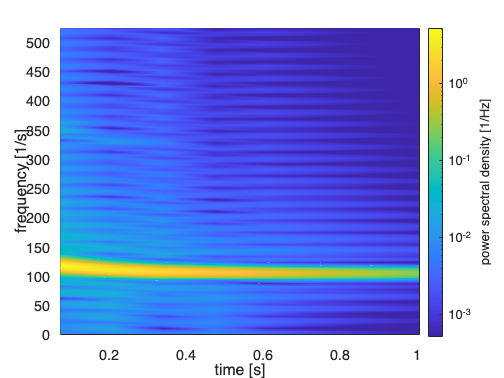

showSpectrogram(xData(indTrain,:), outdof);
ylim([0,abs(lambda(1))/2/pi*5])

We plot theobservables of interest over time for closer inspection. 

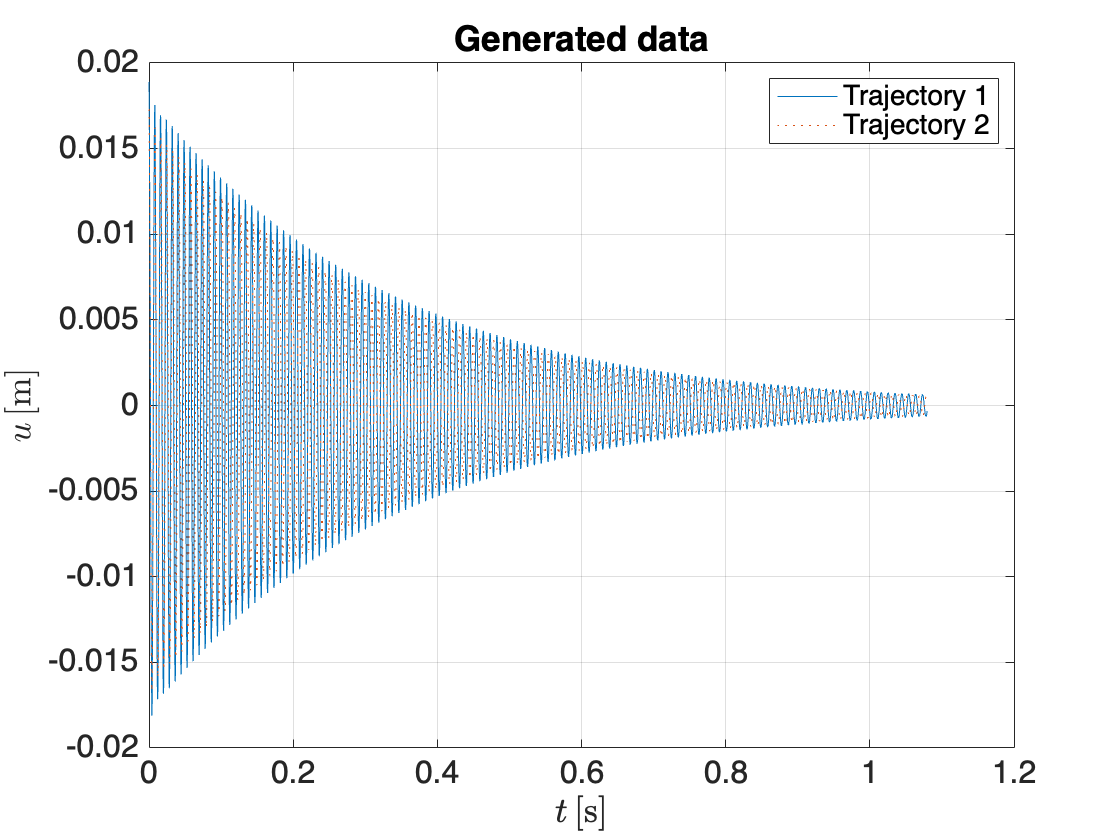

customFigure();
plot(xData{1,1}, xData{1,2}(outdof,:), xData{2,1}, xData{2,2}(outdof,:), ':');
xlabel('$t \, [$s$]$','Interpreter','latex'); ylabel('$q_B \, [$m$]$','Interpreter','latex'); 
legend({'Trajectory 1', 'Trajectory 2'})

## Truncate transient data from trajectories

We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval |sliceInt|.

sliceInt = [4*slowTimeScale, endTime];
xDataTrunc = sliceTrajectories(xData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are initialized to lie close to the manifold of interest that is tangent at the origin to the eigenspace spanned by the columns of $\mathbf{V}_e$. 

As we also know the projection $\mathbf{W}_e$ to this eigenspace, we define the modal coordinates as $\mathbf{y} = \mathbf{W}_e \mathbf{x}$. These are the reduced coordinates for our graph style parametrization of the manifold, gauranteed to exists near the origin. We then use the data to learn the nonlinear feature of the manifold geometry, represented via polynomials. Indeed, we seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$\mathbf{x} = \mathbf{V}_e \mathbf{y}  + \mathbf{H}  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where the function $\mathbf{\phi}_{m,2:M}(\mathbf{y})$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $\mathbf{y}$. From SSM theory, the tangent space of the manifold is $\mathbf{V}_e$. The coefficients $\mathbf{H}$are obtained via least squares regression.

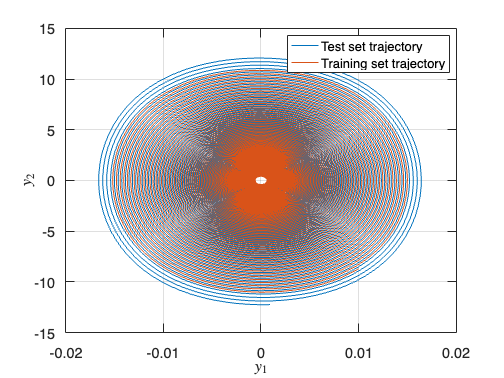

SSMOrder = 3;

% Get projection or modal coordinates 
SSMDim = size(Ve,2);
yDataTrunc = xDataTrunc;
nTraj = size(xDataTrunc,1);
for iTraj = 1:nTraj
    yDataTrunc{iTraj,2} = We*xDataTrunc{iTraj,2};    
end

% Plot reduced coordinates
plotReducedCoordinates(yDataTrunc);
legend({'Test set trajectory', 'Training set trajectory'})
if SSMDim>2
   view(3) 
end
xlabel('$y_1$','interpreter','latex')
ylabel('$y_2$','interpreter','latex')


% Compute nonlinear part of the parametrization
IMInfo = IMGeometry(xDataTrunc(indTrain,:), SSMDim,SSMOrder,...
         'reducedCoordinates',yDataTrunc(indTrain,:),'Ve',Ve,'outdof',outdof); 
IMInfo.chart.map = @(x) We*x;                          

% Parametrization error on test trajectory
normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,...
    yDataTrunc), xDataTrunc);
staticNMTE = mean(normedTrajDist(indTest))*100; % in percentage

disp(['Reconstruction error = ' num2str(staticNMTE) '%'])

Reconstruction error = 0.069406%


## Plot SSM

We plot the SSM geometry in different coordinates: $q_A$ is the axial displacement of the node at the left of the midpoint and $q_B$ is the transversal displacement of the midpoint node.

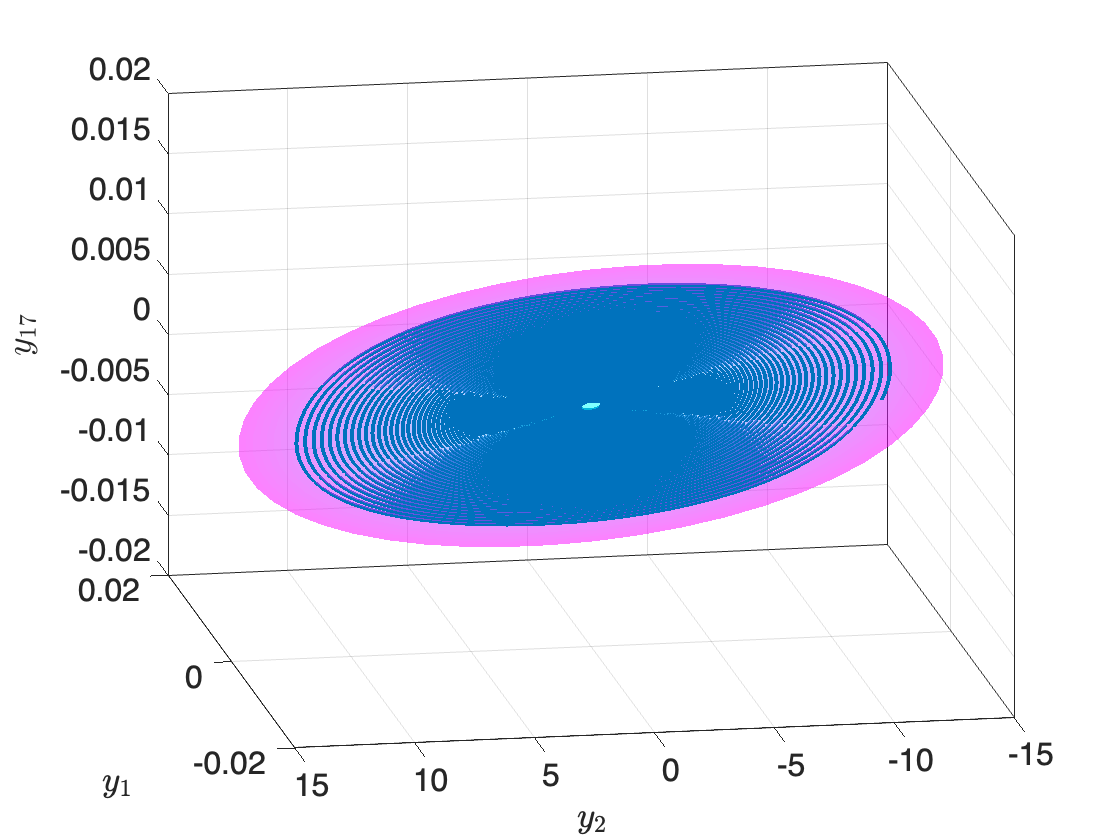

idxPlot = [outdof]; % 3D Plot: y_1, y_2 and idxPlot coordinate
plotSSMandTrajectories(IMInfo, idxPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-100,20); legend('off')
xlabel('$y_1$','interpreter','latex')
ylabel('$y_2$','interpreter','latex')

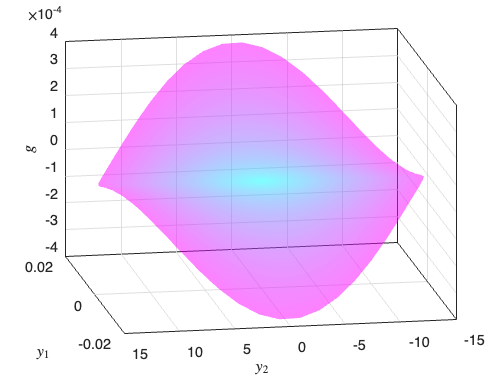

gPlot = @(x) W(5,:)*x; % 3D Plot: y_1, y_2 and gPlot(x) 
plotSSMandTrajectories(IMInfo, gPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-100,20); legend('off')
xlabel('$y_1$','interpreter','latex')
ylabel('$y_2$','interpreter','latex')

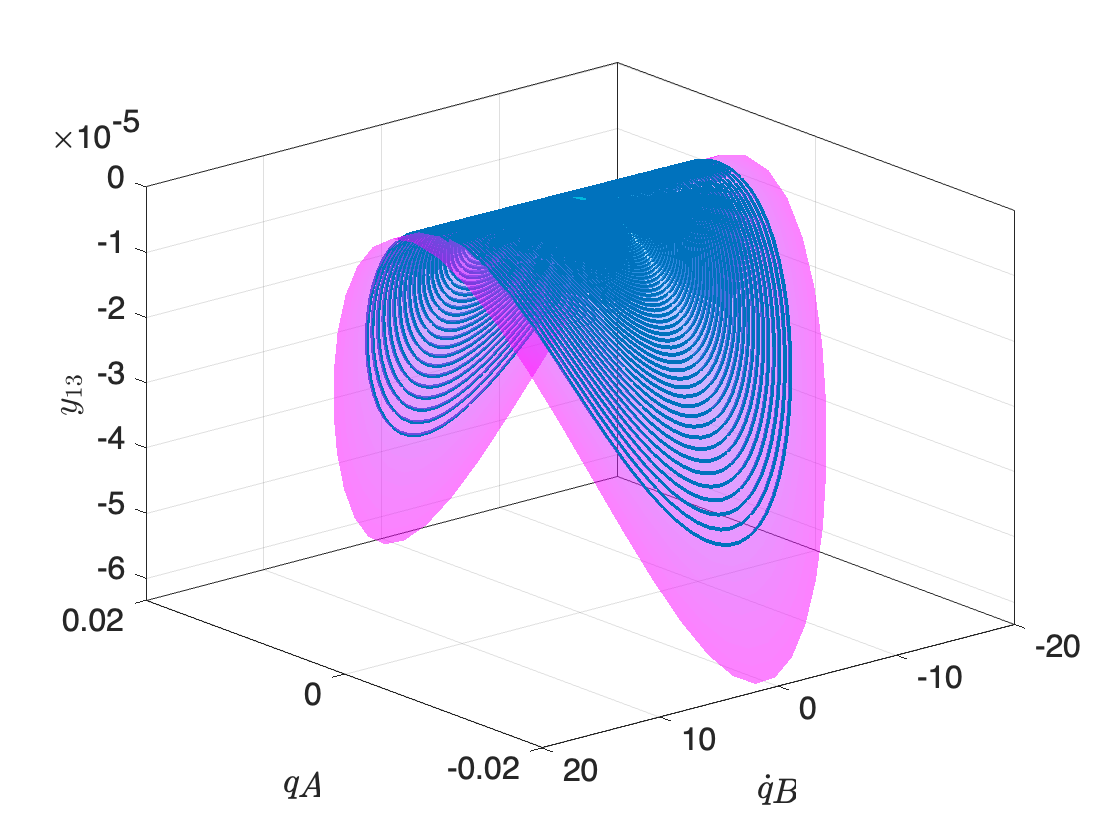

idxPlot = [outdof outdof+n outdof-4]; % 3D Plot: idxPlot(1), idxPlot(2), idxPlot(3) coordinates
plotSSMandTrajectories(IMInfo, idxPlot, xDataTrunc(indTest,:), yDataTrunc(indTest,:))
view(-130,25); legend('off')
xlabel('$q_B$','interpreter','latex')
ylabel('$\dot{q}_B$','interpreter','latex')
xlabel('$q_A$','interpreter','latex')

## Reduced dynamics on the manifold

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsMech` finds the dynamics (considering that we know the linear part)

$\dot{\mathbf{y}}= \mathbf{A}_e \mathbf{y}  + \mathbf{H}_r  \mathbf{\phi}_{m,2:M}(\mathbf{y} )$,

where $\mathbf{\phi}(\mathbf{y})$ again computes a vector of all monomials of $\mathbf{u}$, and $\mathbf{H}_r$ is a matrix of polynomial coefficients of the form


$$\mathbf{H}_r = \left[\matrix{  \mathbf{0} \cr  \mathbf{W}_r } \right]$$


Then, we find from data the extended normal form, which expedites system characterization and computation of periodic forced responses.

ROMOrder = 7;

RDInfo = IMDynamicsMech(yDataTrunc(indTrain,:), ...
    'R_PolyOrd', 1,'N_PolyOrd', ROMOrder, 'style', 'normalform', ...
    'R_coeff',Ae,'rescale',1,'MaxIter',5e3);

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          231.809                           701
     1           3          138.601    0.000254158            556  
     2           5          119.656       0.419688            442  
     3           6          114.236              1            350  
     4           7           105.32              1           30.4  
     5           8          105.176              1             18  
     6           9          105.077              1           4.37  
     7          10          105.069              1           3.77  
     8          11          105.038              1           4.96  
     9          12          105.025              1           4.91  
    10          13           105.01              1           3.89  
    11          14


% We transform the truncated initial condition of our test trajectory according to 
% the obtained change of coordinates, and integrate our reduced order evolution rule 
% to predict the development of the trajectory. 
[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, xDataTrunc);

% Evaluation of reduced dynamics
% The error NMTE is computed as the average distance of the predicted trajectory 
% to the measured one in the full state space.
normedTrajDist = computeTrajectoryErrors(yRec, xDataTrunc);
NMTE = mean(normedTrajDist(indTest))*100;
disp(['Normalized mean trajectory error = ' num2str(NMTE) '%'])

Normalized mean trajectory error = 3.5254%



% We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 
plotReducedCoordinates(yDataTrunc(indTest,:), etaRec(indTest,:))
xlabel('$y_1$','interpreter','latex')
ylabel('$y_2$','interpreter','latex')
legend({'Test set (truncated)', 'Prediction'})
if size(Ae,1)==2
    % Plot SSM with trajectories in the normal form reduced coordinates
    plotSSMandTrajectories(IMInfo, outdof, xDataTrunc(indTest,:), ...
        zRec(indTest,:), 'NFT', RDInfo.transformation.map)
    view(-100,20); legend('off'); zlabel('$q_B$','interpreter','latex')
else
    view(3)
end

We plot the model predictions in physical coordinates. The reduced model seems to do well on previously unseen data, provided that it is close to the manifold.

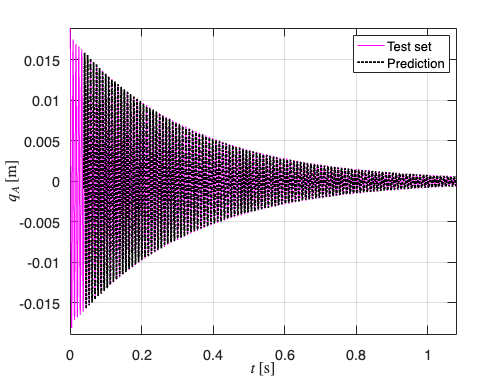

plotTrajectories(xData(indTest,:), yRec(indTest,:), 'm','PlotCoordinate', outdof(1), 'DisplayName', {'Test set', 'Prediction'})
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$q_B \, [$m$]$','Interpreter','latex')

## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency. 

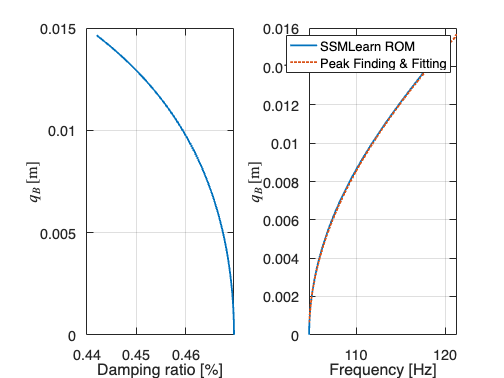

rhoCal = abs(zRec{indTrain(1),2}(1,1));
amplitudeFunction = @(x) x(outdof,:);
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoCal, 'Hz');
subplot(121); ylabel('$q_B \, [$m$]$','Interpreter','latex')
subplot(122); ylabel('$q_B \, [$m$]$','Interpreter','latex')
iTraj = 1;
% Compare with backbone curve from signal processing
[amp,freq,~,~] = PFF(yDataTrunc{iTraj,1},amplitudeFunction(xDataTrunc{iTraj,2}));
plot(freq,amp,':','Linewidth',2)
legend('SSMLearn ROM','Peak Finding & Fitting')

## Adding forcing to the ROM

Outer directions: either consider all outer modes or a subset

nModes = size(V,2);
outerModes = setdiff(1:nModes,masterModes);
Vo = V(:,outerModes); 
Wo = W(outerModes,:); Lo = full(Wo*A*Vo);

Forcing vector

forcingVectors = [zeros(n,1); M\loadVector];

Construct time periodic SSM model

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1,...
         'forcingVectors',forcingVectors,'We',We,'Lo',Lo,'Vo',Vo, 'Wo',Wo);

## Generate Frequency Responses

We compute them also with SSMTool in order to compare the results (see the papers above for additional validations and comparisons).

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 4.698027e-03
modal damping ratio for 2 mode is 1.295171e-02
modal damping ratio for 3 mode is 2.539951e-02
modal damping ratio for 4 mode is 4.202081e-02
modal damping ratio for 5 mode is 6.286832e-02

 The first 10 nonzero eigenvalues are given as 
   1.0e+03 *

  -0.0031 + 0.6577i
  -0.0031 - 0.6577i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0.0903 + 3.5548i
  -0.0903 - 3.5548i
  -0.2472 + 5.8777i
  -0.2472 - 5.8777i
  -0.5533 + 8.7842i
  -0.5533 - 8.7842i

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6 

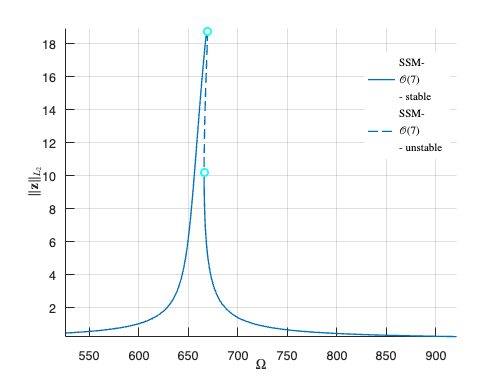

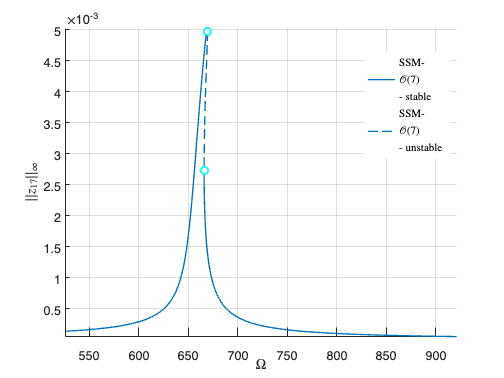

Total time spent on FRC computation upto O(7) = 00:00:18
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

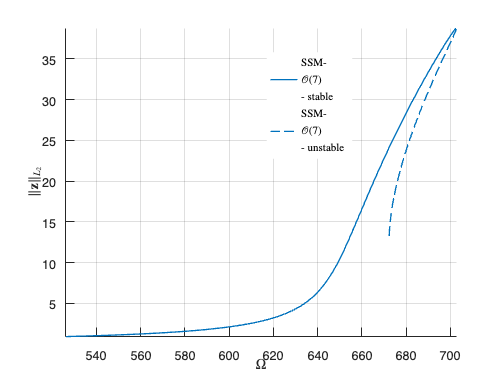

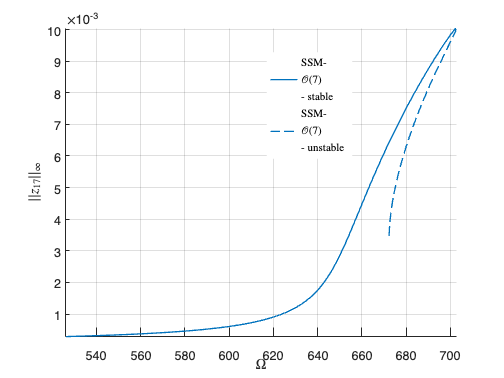

Total time spent on FRC computation upto O(7) = 00:00:08
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

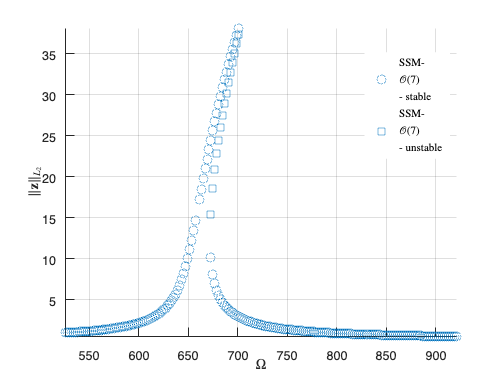

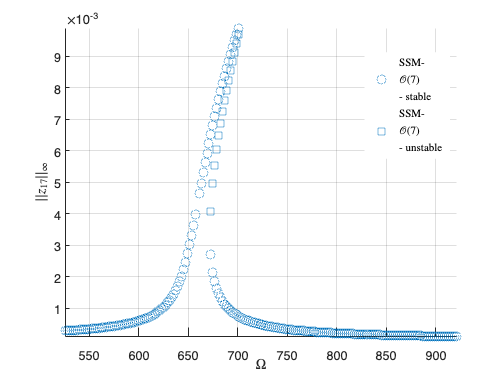

Total time spent on FRC computation upto O(7) = 00:00:03


% Approximately get forcing amplitude to achieve a given maximal amplitude
% response
fscale = abs(RDInfoF.conjugateDynamics.forcingVectors);
amplitudeCal = [0.005 0.01]; forcingAmplitude = amplitudeCal;
for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingAmplitude(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos)/fscale;
end
% Compute forced responses
epsilon = forcingAmplitude;
omegaSpan = abs(imag(lambda(1)))*[0.8 1.4]; % frequency span
% SSMLearn: either numerical solution
%[FRCSSMLearn] = continuationFRCep(IMInfoF, RDInfoF, epsilon, omegaSpan,@(x) x(outdof,:), [1],[1 2], 'SSMLearnFRC');
% or analytical one
FRCSSMLearn = analyticalFRC(IMInfoF, RDInfoF, epsilon, @(x) x(outdof,:), BBCInfo.amplitudeNormalForm(pos)*1.1);
% SSMTool
%FRCSSMTool = SSMToolFRCFE(M,C,K,fnl,loadVector,outdof,epsilon,[1 2],ROMOrder,omegaSpan,[1],'SSMToolFRC');
FRCSSMTool = SSMToolFRCcustom(M, C, K, fnl, loadVector, epsilon, outdof, omegaSpan, ROMOrder,2e3); % to pick up some hard continuation points

% Phase correction
for iF = 1:length(epsilon)
    FRCSSMTool.(['F' num2str(iF)]).Nf_Phs = FRCSSMTool.(['F' num2str(iF)]).Nf_Phs + pi;
end

## **Plot results**

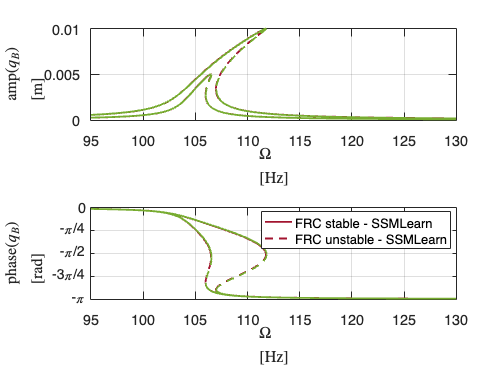

customFigure('subPlot',[2 1]); 
subplot(211)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- Tool','freqscale',2*pi)
xlabel('$$\Omega$$ [Hz]','interpreter','latex')
ylabel('$$\mathrm{amp}(q_{B})$$ [m]','interpreter','latex')
legend('off')
%xlim([ceil(omegaSpan(1)*100)/100 floor(omegaSpan(2)*100)/100]/(2*pi))
xlim([95 130])
subplot(212)
plotFRC(FRCSSMLearn, colors(colSSML,:), '- SSMLearn','y','Phase','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(colSSMT,:), '- SSMTool','y','Phase','freqscale',2*pi)
xlabel('$$\Omega$$ [Hz]','interpreter','latex')
ylabel('$$\mathrm{phase}(q_{B})$$ [rad]','interpreter','latex')
ylim([-pi 0])
set(gca,'YTick',[-pi -3/4*pi -pi/2 -pi/4 0])
set(gca,'YTickLabel',{'-\pi', '-3\pi/4', '-\pi/2', '-\pi/4', '0'})
%xlim([ceil(omegaSpan(1)*100)/100 floor(omegaSpan(2)*100)/100]/(2*pi))
xlim([95 130])

## Test Reduced & Normal form dynamics

Here we simulate a forced periodic solution predicted by the ROM on the full system.


iForcingAmplitude = 1; % index for the desired forcing amplitude in the vector forcingAmplitude
FRCSSMLearnCurr = FRCSSMLearn.([ 'F' num2str(iForcingAmplitude)]);
resonanceBeforeAfter = 1; % 1: before, 2: after
FRCSSMLearnCurrFreq = FRCSSMLearnCurr.Freq(resonanceBeforeAfter,:);
FRCSSMLearnCurrZIC = FRCSSMLearnCurr.z_IC(resonanceBeforeAfter,:);

% Initial condition and parameters
iForcingFrequency = 98; % distance to resonance in percentage
iOmega = floor( iForcingFrequency/101 * length(FRCSSMLearnCurrFreq)) + 1;
fOmegaTest = FRCSSMLearnCurrFreq(iOmega); 
z0 = [FRCSSMLearnCurrZIC(iOmega); conj(FRCSSMLearnCurrZIC(iOmega))];
fAmpTest = forcingAmplitude(iForcingAmplitude); fPhaseTest = 0; Npers = 1;
tTest = linspace(0,Npers*2*pi/min(fOmegaTest),1000*Npers+1);
optionsODE = odeset('RelTol',1e-6,'AbsTol',1e-10);

% Simuluate the reduced system
Nforced =@(t,z) RDInfoF.conjugateDynamics.map(t,z,fOmegaTest,fAmpTest,fPhaseTest);
tic
[~,zTest] = ode45(Nforced,tTest,z0,optionsODE); zTest = transpose(zTest);
toc

Elapsed time is 0.048998 seconds.


yTestRec = RDInfoF.transformation.map(tTest,zTest,fOmegaTest,fAmpTest,fPhaseTest); 
xTestRec = IMInfoF.parametrization.map(tTest,yTestRec,fOmegaTest,fAmpTest,fPhaseTest); 
ampTestRec = amplitudeFunction(xTestRec);
xTrajForcedRec = {tTest, xTestRec};

% Simuluate the full system
xIC = xTestRec(:,1); NpersF = Npers;
physicalForcing = @(t) real( ((fAmpTest.*exp(1i*fPhaseTest)).*forcingVectors)*exp(1i*(transpose(fOmegaTest)*t)) );
Fforced = @(t,x) F(t,x) + physicalForcing(t);
tic
xTrajForced = integrateTrajectories(Fforced, [0 NpersF*2*pi/min(fOmegaTest)], xIC, 1000*NpersF+1);

simulating trajectory 1 of 1...


toc

Elapsed time is 0.182997 seconds.


tTestF = xTrajForced{1,1}; xTest = xTrajForced{1,2}; 
ampTest = amplitudeFunction(xTest); 
yTest = IMInfo.chart.map(xTest);

% Error in percentage
NMTE = computeTrajectoryErrors(xTrajForcedRec, xTrajForced)*100

NMTE = 0.6397

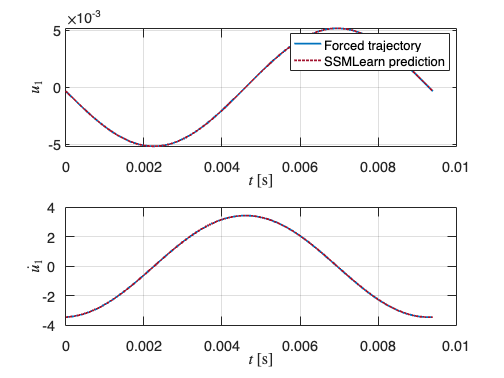


% Plot Results
customFigure('subPlot',[2 1]); subplot(211) 
plot(tTestF,yTest(1,:),'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,yTestRec(1,:),':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
legend
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$u_1$','Interpreter','latex')
subplot(212) 
plot(tTestF,yTest(2,:),'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,yTestRec(2,:),':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$\dot{u}_1$','Interpreter','latex')

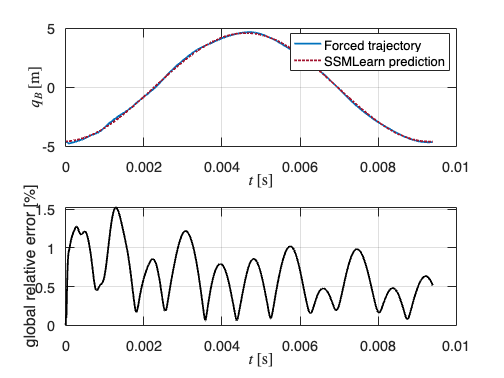

customFigure('subPlot',[2 1]); subplot(211) 
indPlot = 54;
plot(tTestF,xTest(indPlot,:),'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,xTestRec(indPlot,:),':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
legend
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$q_B \, [$m$]$','Interpreter','latex')
subplot(212) 
plot(tTestF,100 * sqrt(sum((xTest-xTestRec).^2)) / max(sqrt(sum((xTest).^2))),'k','Linewidth',2);
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('global relative error [%]')

Here we simulate the transient towards a forced periodic solution predicted by the ROM on the full system.


iForcingAmplitude = 2; % index for the desired forcing amplitude in the vector forcingAmplitude
FRCSSMLearnCurr = FRCSSMLearn.([ 'F' num2str(iForcingAmplitude)]);
resonanceBeforeAfter = 2; % 1: before, 2: after
FRCSSMLearnCurrFreq = FRCSSMLearnCurr.Freq(resonanceBeforeAfter,:);
FRCSSMLearnCurrZIC = FRCSSMLearnCurr.z_IC(resonanceBeforeAfter,:);

% Initial condition and parameters
iForcingFrequency = 60; % distance to resonance in percentage 
iForcingFrequencyIC = 90; % distance to resonance in percentage IC
iOmega = floor( iForcingFrequency/101 * length(FRCSSMLearnCurrFreq)) + 1;
fOmegaTest = FRCSSMLearnCurrFreq(iOmega); 
z0 = zeros(2,1); 
iOmegaIC = floor(iForcingFrequencyIC/101 * length(FRCSSMLearnCurrFreq)) + 1;
z0 = [FRCSSMLearnCurrZIC(iOmegaIC); conj(FRCSSMLearnCurrZIC(iOmegaIC))]

z0 =   -0.3014 + 0.0733i
  -0.3014 - 0.0733i


fAmpTest = forcingAmplitude(iForcingAmplitude); fPhaseTest = 0; Npers = 50;
tTest = linspace(0,Npers*2*pi/min(fOmegaTest),1000*Npers+1);
optionsODE = odeset('RelTol',1e-6,'AbsTol',1e-10);

% Simuluate the reduced system
Nforced =@(t,z) RDInfoF.conjugateDynamics.map(t,z,fOmegaTest,fAmpTest,fPhaseTest);
tic
[~,zTest] = ode45(Nforced,tTest,z0,optionsODE); zTest = transpose(zTest);
toc

Elapsed time is 0.295825 seconds.


yTestRec = RDInfoF.transformation.map(tTest,zTest,fOmegaTest,fAmpTest,fPhaseTest); 
xTestRec = IMInfoF.parametrization.map(tTest,yTestRec,fOmegaTest,fAmpTest,fPhaseTest); 
ampTestRec = amplitudeFunction(xTestRec);
xTrajForcedRec = {tTest, xTestRec};

% Simuluate the full system
xIC = xTestRec(:,1); NpersF = Npers;
physicalForcing = @(t) real( ((fAmpTest.*exp(1i*fPhaseTest)).*forcingVectors)*exp(1i*(transpose(fOmegaTest)*t)) );
Fforced = @(t,x) F(t,x) + physicalForcing(t);
tic
xTrajForced = integrateTrajectories(Fforced, [0 NpersF*2*pi/min(fOmegaTest)], xIC, 1000*NpersF+1);

simulating trajectory 1 of 1...


toc

Elapsed time is 24.282053 seconds.


tTestF = xTrajForced{1,1}; xTest = xTrajForced{1,2}; 
ampTest = amplitudeFunction(xTest); 
yTest = IMInfo.chart.map(xTest);

NMTE = computeTrajectoryErrors(xTrajForcedRec, xTrajForced)*100

NMTE = 0.7375

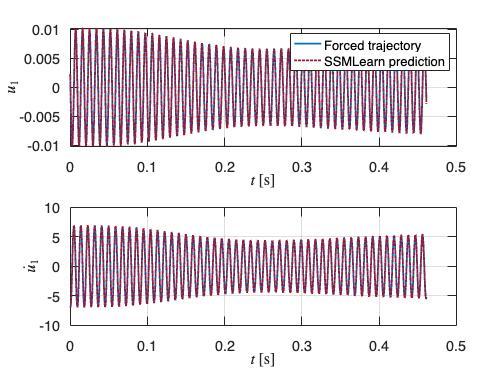


% Plot Results
customFigure('subPlot',[2 1]); subplot(211) 
plot(tTestF,yTest(1,:),'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,yTestRec(1,:),':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
legend
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$u_1$','Interpreter','latex')
subplot(212) 
plot(tTestF,yTest(2,:),'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,yTestRec(2,:),':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$\dot{u}_1$','Interpreter','latex')

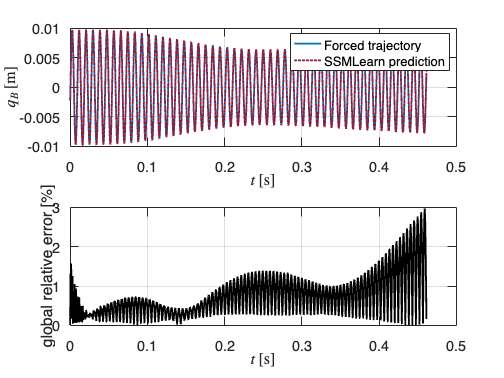


customFigure('subPlot',[2 1]); subplot(211) 
plot(tTestF,ampTest,'Linewidth',2,'DisplayName','Forced trajectory');
plot(tTest,ampTestRec,':','Color',colors(colSSML,:),'Linewidth',2,'DisplayName','SSMLearn prediction');
legend
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('$q_B \, [$m$]$','Interpreter','latex')
subplot(212) 
plot(tTestF,100 * sqrt(sum((xTest-xTestRec).^2)) / max(sqrt(sum((xTest).^2))),'k','Linewidth',2);
xlabel('$t \, [$s$]$','interpreter','latex')
ylabel('global relative error [%]')